model = createpde("structural","static-solid");

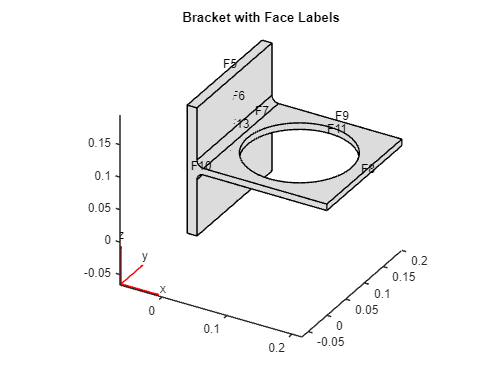

importGeometry(model,"BracketWithHole.stl");
figure
pdegplot(model,"FaceLabels","on")
view(30,30);
title("Bracket with Face Labels")

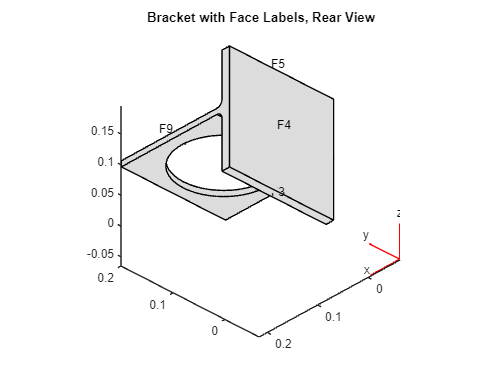

figure
pdegplot(model,"FaceLabels","on")
view(-134,-32)
title("Bracket with Face Labels, Rear View")

structuralProperties(model,"YoungsModulus",200e9, ...
                           "PoissonsRatio",0.3);

structuralBC(model,"Face",4,"Constraint","fixed");

structuralBoundaryLoad(model,"Face",8,"SurfaceTraction",[0;0;-1e4]);

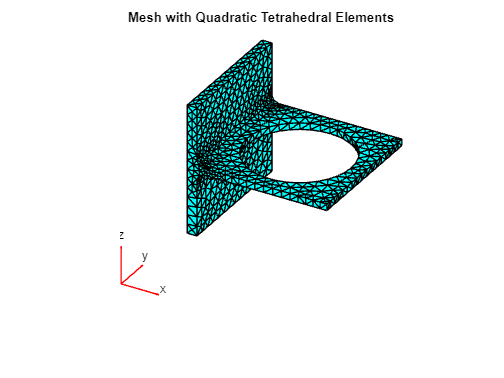

generateMesh(model);
figure
pdeplot3D(model)
title("Mesh with Quadratic Tetrahedral Elements");

result = solve(model)

result =   StaticStructuralResults with properties:

      Displacement: [1×1 FEStruct]
            Strain: [1×1 FEStruct]
            Stress: [1×1 FEStruct]
    VonMisesStress: [5993×1 double]
              Mesh: [1×1 FEMesh]


minUz = min(result.Displacement.uz);
fprintf("Maximal deflection in the z-direction is %g meters.", minUz)

Maximal deflection in the z-direction is -4.43075e-05 meters.

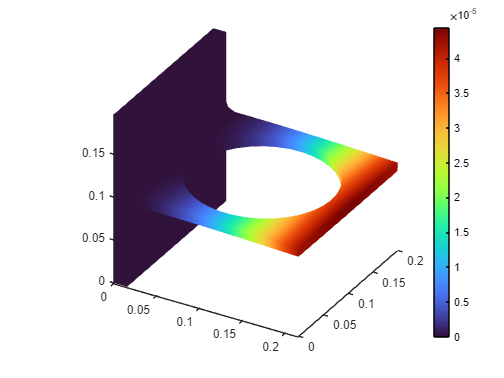

% Data to visualize
meshData = result.Mesh;
nodalData = result.Displacement.Magnitude;
deformationData = result.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",100, ...
    "ColorLimits",[0 4.434e-05]);


% Clear temporary variables
clearvars meshData nodalData deformationData

matrices = assembleFEMatrices(model)

matrices = struct with fields:
    K: [17979×17979 double]
    A: [17979×17979 double]
    F: [17979×1 double]
    Q: [17979×17979 double]
    G: [17979×1 double]
    H: [2847×17979 double]
    R: [2847×1 double]
    M: [17979×17979 double]


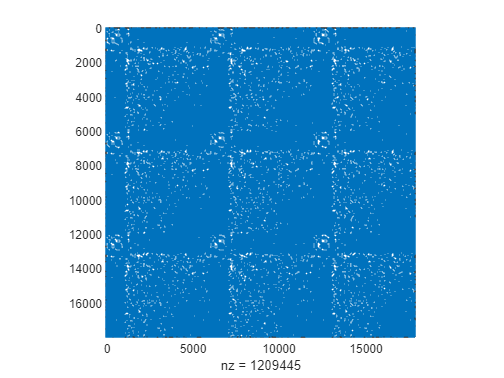

figure
spy(matrices.K)